**INTERPOLACIÓN POLINOMIAL**

1. Polinomios

% p(x) = 2*x^3 - 6*x + 5
pol1 = @(x) 2*x.^3 - 6*x + 5

pol1 = function_handle with value:
    @(x)2*x.^3-6*x+5


% Evaluando en x = 2
x0 = 3;
pol1(x0)

ans = 41

% Declar polinomios usando vectores de coeficientes
pol2 = [ 2 0 -6 5 ]

pol2 =      2     0    -6     5


% Evaluando en x = 2
polyval(pol2,x0)

ans = 41

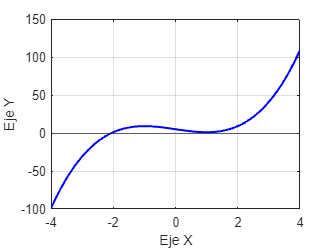

% Gráfica del polinomio
xx = -4:0.1:4;
% xx = linspace(-4,4,50)
yy = polyval(pol2,xx);
figure(1); clf;
plot(xx,yy,'-b','LineWidth',1.5); grid on;
xlabel('Eje X'); ylabel('Eje Y');
yline(0)

% Construir polinomios a partir de sus raíces:
r1 = 4, r2 = 6

r1 = 4

r2 = 6

pol3 = poly([r1 r2])

pol3 =      1   -10    24


% Raíces de un polinomio
roots(pol3)

ans =     6.0000
    4.0000


**2. Interpolación Polinomial: Método 1 - SEL**

xdata = [ -2 0 3 ]'

xdata =     -2
     0
     3


ydata = [ 5 1 7 ]'

ydata =      5
     1
     7


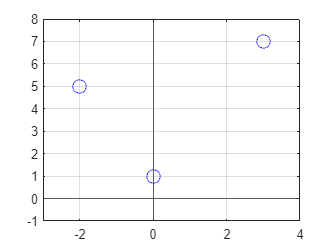


figure(2); clf;
plot(xdata,ydata,'ob','MarkerSize',10); grid on;
axis([-3 4 -1 8]);
xline(0); yline(0)

% A = [ xdata.^2 xdata ones(length(xdata),1) ]
% A = [ xdata.^2 xdata.^1 xdata.^0 ]
A = vander(xdata)

A =      4    -2     1
     0     0     1
     9     3     1


b = ydata

b =      5
     1
     7


coef = A\b

coef =     0.8000
   -0.4000
    1.0000


% coef2 = linsolve(A,b)
% Usando el comando polyfit:
pol4 = polyfit(xdata,ydata,length(xdata)-1)

pol4 =     0.8000   -0.4000    1.0000


**3. Interpolación con Polinomios Básicos de Lagrange**

xdata = [ -2 0 3 ]';
ydata = [ 5 1 7 ]';

% N = length(xdata);
% p = zeros(1,N);
% for k = 1:N
%     num = poly(xdata([1:k-1,k+1:N]));
%     den = polyval(num,xdata(k));
%     L = num/den;
%     p = p + ydata(k)*L;
% end

pol5 = lagrange(xdata,ydata)

pol5 =     0.8000   -0.4000    1.0000


% Confirmando el polinomio:
polyval(pol5,xdata)

ans =     5.0000
    1.0000
    7.0000


xx = -3:0.1:4

xx =    -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000


yy = polyval(pol5,xx);
figure(3); clf;
plot(xdata,ydata,'or','MarkerSize',10,'LineWidth',2); grid on; hold;

Current plot held


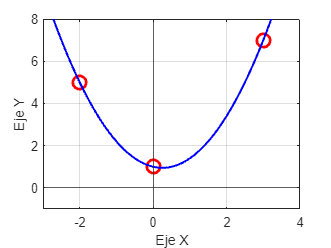

plot(xx,yy,'-b','LineWidth',1.5); grid on;
axis([-3 4 -1 8]);
xline(0); yline(0)
xlabel('Eje X'); ylabel('Eje Y');

**4. Polinomio con Diferencias Divididas de Newton:**

xdata = [ -2 0 3 ]';
ydata = [ 5 1 7 ]';

% N = length(xdata);
% M = zeros(N);
% M(1:N,1) = ydata;
% for k=1:N-1
%     dx = xdata(k+1:N)-xdata(1:N-k);
%     dy = diff(ydata)./dx;
%     M(1:N-k,k+1) = dy;
%     ydata = dy;
% end
% M = [xdata M]
% b = M(1,2:end)
% p = b(1)
% for k = 2:N
%     p = [0 p]+b(k)*poly(xdata(1:k-1))
% end

pol6 = polynewton(xdata,ydata)

pol6 =     0.8000   -0.4000    1.0000


**5. Interpolación con Spline Cúbico Natural:**

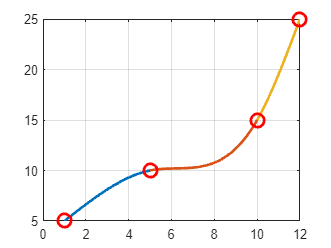

S =    -0.0259         0    1.6641    5.0000
    0.0852   -0.3106    0.4218   10.0000
   -0.1613    0.9681    3.7093   15.0000


% Para la función splinenatural considerar data como vector fila
xdata = [1 5 10 12];
ydata = [5 10 15 25];

% figure(4); clf;
% plot(xdata,ydata,'ob','MarkerSize',10,'LineWidth',2); grid on;
% xlabel('Eje X'); ylabel('Eje Y');
% axis([xdata(1) xdata(end) ydata(1) ydata(end)]);
% xline(0); yline(0)
S = splinenatural(xdata,ydata)

FUNCIONES:

function p = lagrange(x,y)
    n=length(x);
    p=zeros(1,n);
    for k=1:n
        num=poly(x([1:k-1,k+1:n]));
        den=polyval(num,x(k));
        L=num/den;
        p=p+y(k)*L;
    end
end

function M=tabladif(x,y)
    n=length(x);
    M=zeros(n);
    M(1:n,1)=y;
    for k=1:n-1
        dx=x(k+1:n)-x(1:n-k);
        dy=diff(y)./dx;
        M(1:n-k,k+1)=dy;
        y=dy;
    end
    M=[x M];
end

function p=polynewton(x,y)
    M=tabladif(x,y);
    n=length(x);
    b=M(1,2:end);
    p=b(1);
    for k=2:n
        p=[0 p]+b(k)*poly(x(1:k-1));
    end
end

function S = splinenatural(X,Y)
    N=length(X)-1; H=diff(X); E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E'); g=A\b;
    g=[g0 g' gn];
    figure(7); clf;
    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy,'LineWidth',2), hold on
    end
    plot(X,Y,'or','MarkerSize',10,'LineWidth',2);
    grid on, hold off
end